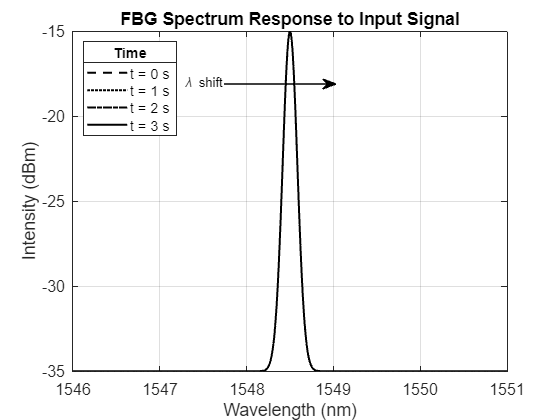

% FBG Spectrum Response to Arbitrary Input Signal
clear all;
close all;

% Basic FBG parameters
lambda_start = 1546;       % Start wavelength (nm)
lambda_end = 1551;        % End wavelength (nm)
lambda = lambda_start:0.01:lambda_end;  % Wavelength range (nm)
lambda_B = 1548.5;        % Initial Bragg wavelength (nm)
bandwidth = 0.2;          % Spectral width (nm)
max_intensity = -15;      % Peak intensity (dBm)
min_intensity = -35;      % Background intensity (dBm)

% FBG sensitivity parameters
strain_sensitivity = 1.2;  % pm/microstrain
temp_sensitivity = 10;    % pm/°C

% Create arbitrary input signal here
% Example 1: Sinusoidal strain input
t = [0, 1, 2, 3];        % Time points (can be modified)
% You can replace this with any arbitrary input function
input_signal = 100 * sin(2*pi*0.5*t);  % Example: 100 microstrain amplitude

% Calculate wavelength shifts based on input signal
wavelength_shifts = strain_sensitivity * input_signal / 1000;  % Convert to nm

% Initialize figure
figure;
hold on;
grid on;

% Plot style properties
line_styles = {'--', ':', '-.', '-'};
colors = {'k', 'k', 'k', 'k'};

% Generate and plot spectrum for each time point
for i = 1:length(t)
    % Calculate shifted Bragg wavelength
    lambda_B_shifted = lambda_B + wavelength_shifts(i);
    
    % Generate FBG reflection spectrum using Gaussian approximation
    intensity = min_intensity + (max_intensity - min_intensity) * ...
        exp(-(lambda - lambda_B_shifted).^2 / (2 * (bandwidth/2.355)^2));
    
    % Plot with appropriate line style
    plot(lambda, intensity, line_styles{i}, 'Color', colors{i}, 'LineWidth', 1.5);
end

% Customize plot
xlabel('Wavelength (nm)');
ylabel('Intensity (dBm)');
title('FBG Spectrum Response to Input Signal');

% Create legend with time values
legend_entries = cell(length(t), 1);
for i = 1:length(t)
    legend_entries{i} = ['t = ' num2str(t(i)) ' s'];
end

% Create legend with a text label above it
leg = legend(legend_entries, 'Location', 'northwest');
title(leg, 'Time');  % This is the correct way to set the legend title

% Add arrow to indicate shift direction
% if max(wavelength_shifts) > 0
%     arrow_text = '\lambda shift';
% else
%     arrow_text = '\lambda shift';
% end
% annotation('textarrow', [0.4 0.6], [0.8 0.8], ...
%     'String', arrow_text, ...
%     'HeadStyle', 'vback2');

% Set axis limits
xlim([lambda_start lambda_end]);
ylim([-35 -15]);

% Additional plot formatting
box on;
set(gca, 'FontSize', 12);

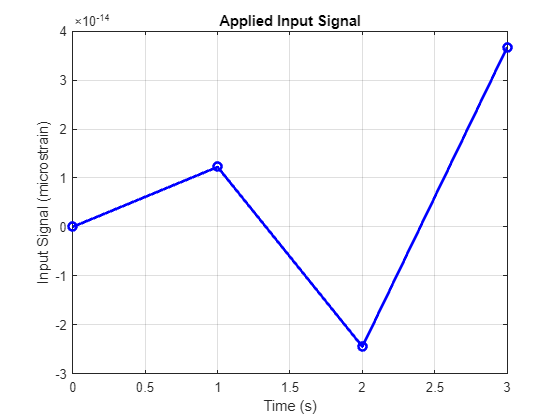


% Plot the input signal for reference
figure;
plot(t, input_signal, 'b-o', 'LineWidth', 2);
grid on;
xlabel('Time (s)');
ylabel('Input Signal (microstrain)');
title('Applied Input Signal');